Data 

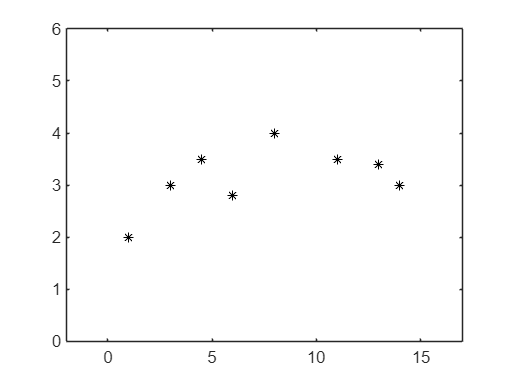

x = [1 3 4.5 6 8 11 13 14];
y = [2 3 3.5 2.8 4 3.5 3.4 3];
plot(x,y,'k*')
axis([-2 17 0 6])

Linear interpolation (points 1 & 8)

xinterp =[x(1) x(8)]

xinterp =      1    14


yinterp =[y(1) y(8)]

yinterp =      2     3



p1 = polyfit(xinterp, yinterp, 1)

p1 =     0.0769    1.9231



xx = 1:0.1:14;
yy1 = polyval(p1,xx)

yy1 =     2.0000    2.0077    2.0154    2.0231    2.0308    2.0385    2.0462    2.0538    2.0615    2.0692    2.0769    2.0846    2.0923    2.1000    2.1077    2.1154    2.1231    2.1308    2.1385    2.1462    2.1538    2.1615    2.1692    2.1769    2.1846    2.1923    2.2000    2.2077    2.2154    2.2231    2.2308    2.2385    2.2462    2.2538    2.2615    2.2692    2.2769    2.2846    2.2923    2.3000    2.3077    2.3154    2.3231    2.3308    2.3385    2.3462    2.3538    2.3615    2.3692    2.3769


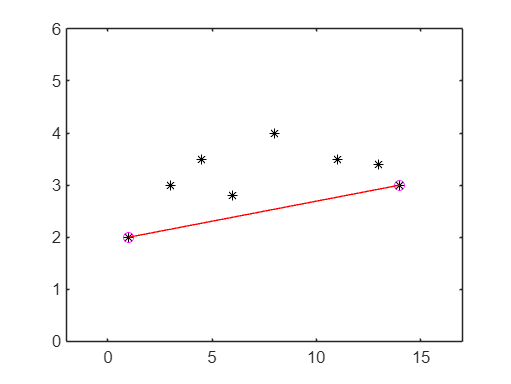


figure
plot(x,y,'k*')
hold on
plot(xinterp,yinterp,'mo')
plot(xx,yy1,'r-')
axis([-2 17 0 6])

Quadratic polynomial interpolation (points 1,5,8)

xinterp =[x(1) x(5) x(8)]

xinterp =      1     8    14


yinterp =[y(1) y(5) y(8)]

yinterp =      2     4     3



p2 = polyfit(xinterp, yinterp, 2)

p2 =    -0.0348    0.5989    1.4359



xx = 1:0.1:14;
yy2 = polyval(p2,xx)

yy2 =     2.0000    2.0526    2.1045    2.1557    2.2062    2.2560    2.3051    2.3535    2.4012    2.4482    2.4945    2.5401    2.5851    2.6293    2.6728    2.7157    2.7578    2.7992    2.8400    2.8801    2.9194    2.9581    2.9960    3.0333    3.0699    3.1058    3.1410    3.1754    3.2092    3.2423    3.2747    3.3064    3.3374    3.3677    3.3974    3.4263    3.4545    3.4820    3.5089    3.5350    3.5604    3.5852    3.6092    3.6326    3.6552    3.6772    3.6985    3.7190    3.7389    3.7581


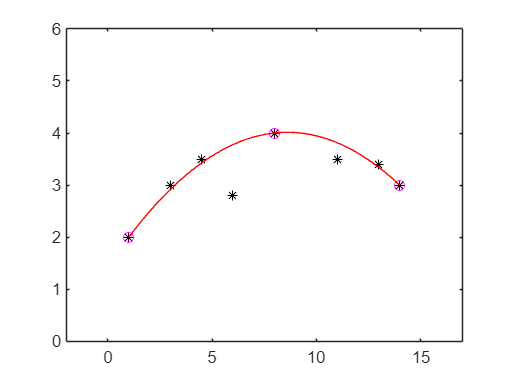


figure
plot(x,y,'k*')
hold on
plot(xinterp,yinterp,'mo')
plot(xx,yy2,'r-')
axis([-2 17 0 6])

Cubic polynomial interpolation (points 1,3,6,8)

xinterp =[x(1) x(3) x(6) x(8)]

xinterp =     1.0000    4.5000   11.0000   14.0000


yinterp =[y(1) y(3) y(6) y(8)]

yinterp =     2.0000    3.5000    3.5000    3.0000



p3 = polyfit(xinterp, yinterp, 3)

p3 =     0.0019   -0.0750    0.7909    1.2822



xx = 1:0.1:14;
yy3 = polyval(p3,xx)

yy3 =     2.0000    2.0640    2.1266    2.1878    2.2478    2.3063    2.3636    2.4195    2.4741    2.5275    2.5795    2.6303    2.6799    2.7282    2.7752    2.8211    2.8657    2.9092    2.9514    2.9925    3.0324    3.0712    3.1089    3.1454    3.1808    3.2151    3.2483    3.2804    3.3115    3.3415    3.3704    3.3984    3.4253    3.4512    3.4761    3.5000    3.5229    3.5449    3.5660    3.5860    3.6052    3.6235    3.6408    3.6572    3.6728    3.6875    3.7014    3.7144    3.7265    3.7379


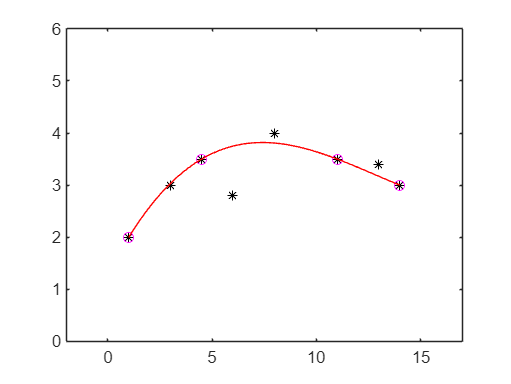


figure
plot(x,y,'k*')
hold on
plot(xinterp,yinterp,'mo')
plot(xx,yy3,'r-')
axis([-2 17 0 6])

7th-order polynomial interpolation


p7 = polyfit(x, y, 7)

p7 =    -0.0001    0.0048   -0.1036    1.1597   -7.0728   22.8676  -34.5103   19.6548



xx = 1:0.1:14;
yy7 = polyval(p7,xx)

yy7 =     2.0000    1.4886    1.1107    0.8485    0.6857    0.6075    0.6002    0.6518    0.7512    0.8884    1.0548    1.2423    1.4441    1.6542    1.8673    2.0788    2.2850    2.4825    2.6689    2.8419    3.0000    3.1420    3.2672    3.3750    3.4654    3.5387    3.5951    3.6353    3.6602    3.6708    3.6680    3.6533    3.6277    3.5927    3.5497    3.5000    3.4451    3.3862    3.3249    3.2624    3.1999    3.1387    3.0798    3.0244    2.9733    2.9275    2.8876    2.8545    2.8285    2.8102


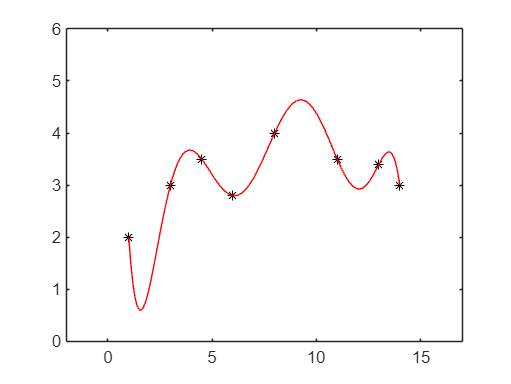


figure
plot(x,y,'k*')
hold on
plot(xx,yy7,'r-')
axis([-2 17 0 6])